close all; clc; clear;
matlab.lang.OnOffSwitchState = 1;

a) Is it a convex optimization problem? 

H = [0 0
     0 2];

fprintf("f(x): \n");

f(x): 


fprintf("%i\n",eig(H));

0
2




H_constraint = [-2  0
                 0 -2];

fprintf("g(x): \n");

g(x): 


fprintf("%i\n",eig(H_constraint));

-2
-2


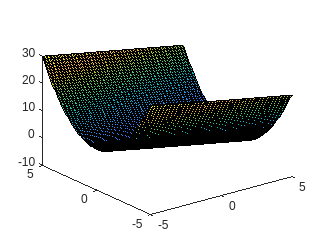


steps = 0.1;
x1 = -5:steps:5;
x2 = -5:steps:5;

[X1, X2] = meshgrid(x1,x2);

X3 = -X1+X2.^2;

surface(X1,X2,X3);
view(3);

contourf(X1,X2,X3);

conditions = zeros(size(X3));
conditions = (-X1.^2-X2.^2+4<=0)

conditions = 101×101 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

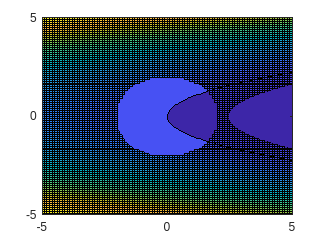


X3(conditions == 0) = NaN;

surface(X1,X2,X3);
view(2);


conditions = zeros(size(X3));
conditions = (-X1.^2-X2.^2+4<=0)

conditions = 101×101 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

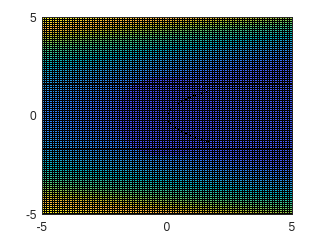


X3(conditions == 0) = NaN;
surface(X1,X2,X3);
view(2);

b) Do global optimal solutions exist? Why? 

c) Does the Abadie constraints qualification hold? Why? 

d) Find all the solutions of the KKT system associated with the problem. 

e) Find local and global optimal solutions exploiting the optimality conditions. 

f) Write the Lagrangian dual problem and try to solve it.